# **Problems Week 4**

**Answer: **[**https://docs.google.com/document/d/1AeXo6Dq09QAKB2OZVKjVcYx_gEVXw9C30GtFnPSqWJA/edit**](https://docs.google.com/document/d/1AeXo6Dq09QAKB2OZVKjVcYx_gEVXw9C30GtFnPSqWJA/edit)

## **P4-1**

**[Overflow Error]** Matlab returns **Inf** when an overflow error in double precision is encountered. Write a script that starts with *n* = 1, calculates *n*! and increases *n* until overflow occurs (number is too big that Matlab can’t handle it). Display the value of *n* that represents the largest factorial that Matlab can handle.

n = 1;
maxValue = realmax('double');

while true
    try
        factorial_n = factorial(n);
        if factorial_n > maxValue
            error('Overflow error');
        end
        n = n + 1;
    catch
        break;
    end
end

fprintf('Highest factorial is: %d\n', n - 1);

Highest factorial is: 170


## **P4-2**

**[Rounding Error]** Approximate the sequence {$\pi^n$} for *n* = 1 to 18 by rounding $\pi$ to 1, 2, 4, and 8 decimal places. Calculate the absolute error for each sequence approximation from the sequence that uses $\pi$ with double precision. Plot the errors for each approximate sequence on the same plot with y-axis between 0 and 5. See if you can figure out how to embed smaller plots within the main plot that zoom in on each of the sequences.

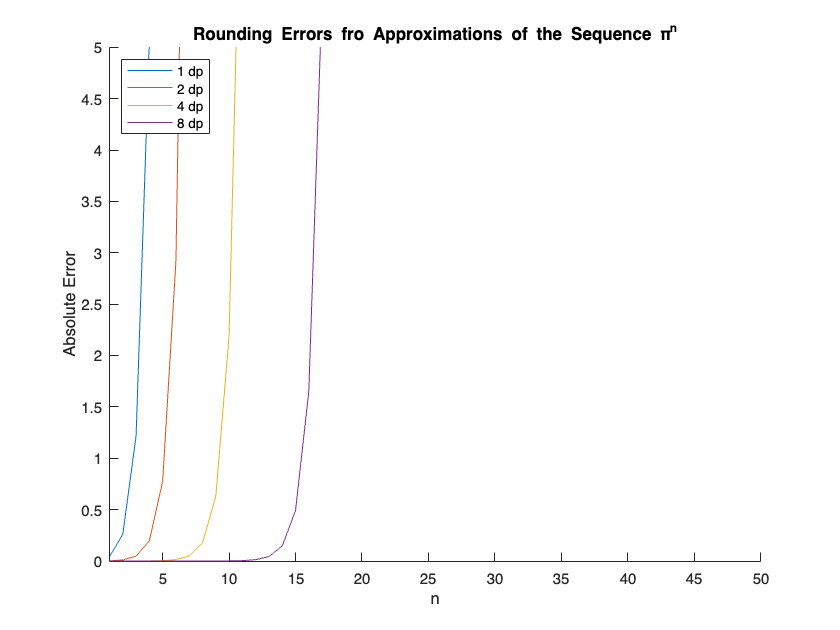

% Define the values of n
n = 1:18;

% Calculate the exact sequence using double precision
exact_sequence = pi.^n;

% Define the decimal places for rounding π
decimal_places = [1, 2, 4, 8];

% Initialize arrays to store the errors for each approximation
errors = zeros(length(decimal_places), length(n));

% Loop through each decimal place
for i = 1:length(decimal_places)
    % Round π to the specified decimal place
    rounded_pi = round(pi, decimal_places(i));
    
    % Calculate the approximate sequence
    approx_sequence = rounded_pi.^n;
    
    % Calculate the absolute error for each term in the sequence
    errors(i, :) = abs(approx_sequence - exact_sequence);
end

% Create a main plot
figure;
hold on;
title('Rounding Errors fro Approximations of the Sequence π^n');
xlabel('n');
ylabel('Absolute Error');
ylim([0, 5]);
xlim([1, 50]);

% Plot the errors for each decimal place
for i = 1:length(decimal_places)
    plot(n, errors(i, :), 'DisplayName', [num2str(decimal_places(i)) ' dp']);
end

% Add a legend to the main plot
legend('Location', 'Northwest');
hold off;

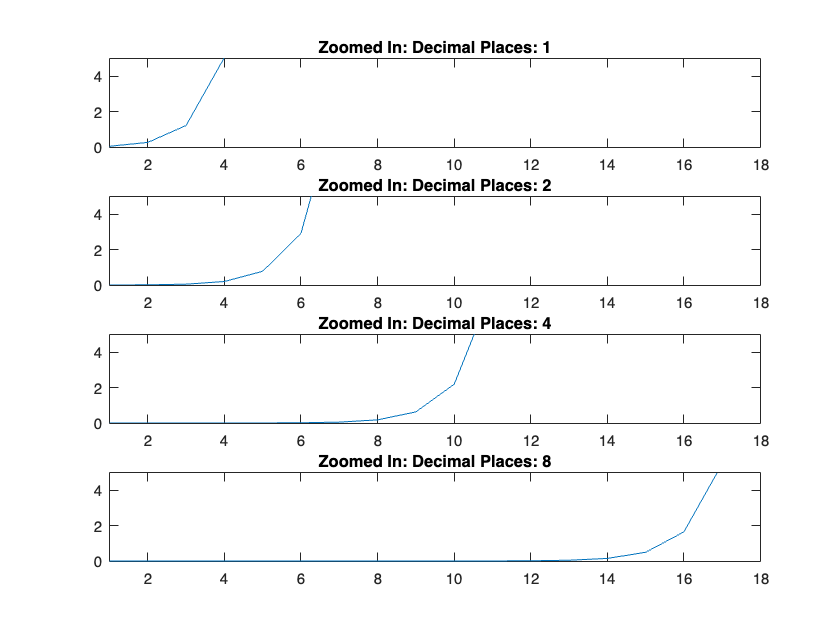

% Create embedded plots for zooming in on errors
figure;
for i = 1:length(decimal_places)
    subplot(length(decimal_places), 1, i);
    plot(n, errors(i, :));
    title(['Zoomed In: Decimal Places: ' num2str(decimal_places(i))]);
    xlim([1, 18]);
    ylim([0, 5]);
end

## **P4-3**

**[Truncation Error]** The Maclaurin series for cos(*x*) is

## 
$$\cos \left(x\right)=\sum_{n=0}^{\infty } \frac{{\left({-1}^n \right)}^n x^{2n} }{\left(2n\right)!}$$


Plot the cosine function in a thick black line between –2π and 2π. On the same graph plot the Maclaurin series approximation for *n* equal to 2, 4, 8 and 16.

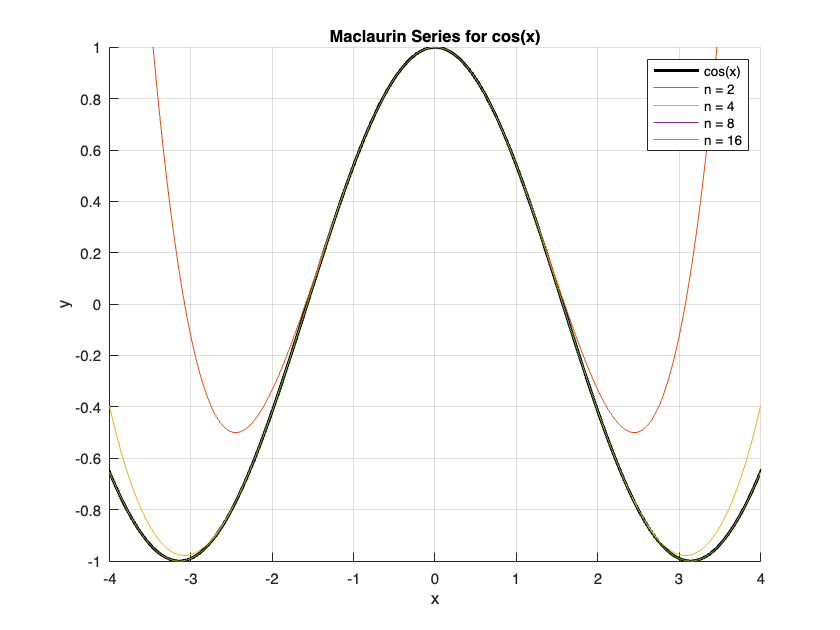

% Define the range for x values
x = linspace(-2*pi, 2*pi, 1000);

% Compute the true cosine values
cos_x = cos(x);

% Initialize variables to store Maclaurin series approximations
n_values = [2, 4, 8, 16];
approximations = zeros(length(n_values), length(x));

% Compute Maclaurin series approximations for different n values
for i = 1:length(n_values)
    n = n_values(i);
    approximation = 0;
    for k = 0:n
        approximation = approximation + ((-1)^k * x.^(2*k)) / factorial(2*k);
    end
    approximations(i, :) = approximation;
end

% Create the plot
figure;
hold on;

% Plot the true cosine function in a thick black line and add a legend entry
plot(x, cos_x, 'k', 'LineWidth', 2);
legend('cos(x)');

% Plot Maclaurin series approximations for n values and add legend entries
for i = 1:length(n_values)
    plot(x, approximations(i, :));
end
legend('cos(x)', 'n = 2', 'n = 4', 'n = 8', 'n = 16');

% Add labels and title
xlabel('x');
ylabel('y');
title('Maclaurin Series for cos(x)');

% Set axis limits
xlim([-4, 4]);
ylim([-1, 1]);

% Turn on the grid
grid on;

% Hold off to end the plotting
hold off;

## **P4-4**

**[Correcting Measurement Data]** Import the data from the file **data_pp4_q4.xls** using the import wizard (or using the **xlsread** command) then plot the Data against Time. The data should be corrected so that all values above 100 are normalised to exactly 100, and all values below –100 are normalised to exactly –100. Plot the corrected data on a subplot below the original.

## **P4-5**

**[True vs. Relative Error]** The Maclaurin series for $e^x$ is 

## 
$$e^x =\sum_{n=0}^{\infty } \frac{x^n }{n!}$$


Plot the true function from 0 to 5 then on the same graph plot the Maclaurin approximations for *n* equal to 1, 2, 4, 8, and 16. Calculate the true absolute and true relative errors then plot these together in a separate graph.

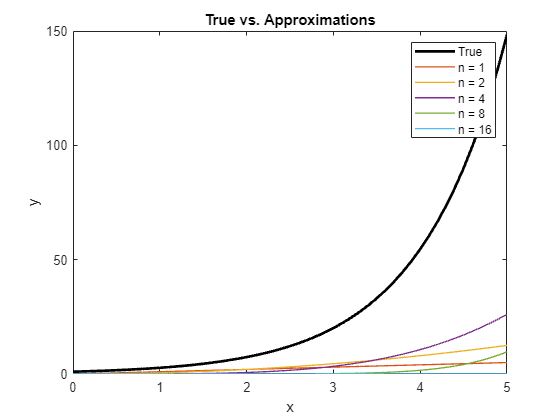

% Define the range of x values
x = 0:0.1:5;

% Calculate true values of e^x
true_values = exp(x);

% Initialize variables to store Maclaurin approximations
n_values = [1, 2, 4, 8, 16];
maclaurin_values = zeros(length(n_values), length(x));

% Calculate Maclaurin approximations for different n values
for i = 1:length(n_values)
    n = n_values(i);
    maclaurin_values(i, :) = sum((x.^n) / factorial(n), 1);
end

% Calculate true absolute and relative errors
true_absolute_errors = abs(true_values - maclaurin_values);
true_relative_errors = true_absolute_errors ./ true_values;

% Create a plot for the true function and Maclaurin approximations
figure;
plot(x, true_values, 'k-', 'LineWidth', 2); % True function
hold on;

for i = 1:length(n_values)
    plot(x, maclaurin_values(i, :), 'LineWidth', 1);
end

legend('True', 'n = 1', 'n = 2', 'n = 4', 'n = 8', 'n = 16');
title('True vs. Approximations');
xlabel('x');
ylabel('y');
hold off;

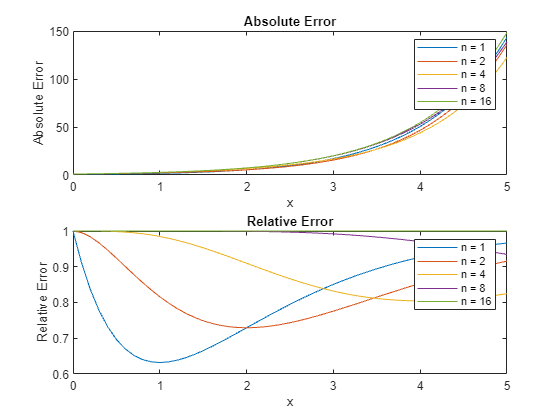

figure;

subplot(2, 1, 1);
plot(x, true_absolute_errors, 'LineWidth', 0.5);
legend('n = 1', 'n = 2', 'n = 4', 'n = 8', 'n = 16');
title('Absolute Error');
xlabel('x');
ylabel('Absolute Error');

subplot(2, 1, 2);
plot(x, true_relative_errors, 'LineWidth', 0.5);
legend('n = 1', 'n = 2', 'n = 4', 'n = 8', 'n = 16');
title('Relative Error');
xlabel('x');
ylabel('Relative Error');

## **P4-6**

**[Convergence with Absolute Error Criterion]** The series 

## 
$$\sum_{n=0}^{\infty } \frac{4^{n+1} }{\left(3n+1\right)!}$$


is convergent. Write a script that finds the value the series converges to by using a loop and the absolute approximate error with a tolerance of 0.0001 (stopping criterion).

% Initialize variables
n = 0; % Initialize n
sum_series = 0; % Initialize the sum of the series
tolerance = 0.0001; % Tolerance for absolute error
absolute_error = 1; % Initialize the absolute error
term = 1; % Initialize the current term

% Loop until the absolute error is less than the tolerance
while absolute_error >= tolerance
    % Calculate the current term of the series
    term = (4^(n+1)) / factorial(3*n+1);
    
    % Add the current term to the sum
    sum_series = sum_series + term;
    
    % Calculate the absolute error
    absolute_error = abs(term);
    
    % Increment n for the next iteration
    n = n + 1;
    
    % Display the current absolute error
    fprintf('Absolute error is: %.5f\n', absolute_error);
end

Absolute error is: 4.00000
Absolute error is: 0.66667
Absolute error is: 0.01270
Absolute error is: 0.00007


n = n - 1;

% Display the final result
fprintf('The sum has converged to %.4f\n', sum_series);

The sum has converged to 4.6794


fprintf('The number of terms required is %d\n', n);

The number of terms required is 3


## **P4-7**

**[Convergence with Relative Error Criterion] **Write a script that finds the value that the series in question 6 converges to, by using a loop and the relative approximate error with a tolerance of 0.0001 (stopping criterion). Compare the results of this question with question 6.

% Initialize variables
n = 0; % Initialize n
sum_series = 0; % Initialize the sum of the series
tolerance = 0.0001; % Tolerance for relative error
relative_error = 1; % Initialize the relative error
term = 1; % Initialize the current term

% Loop until the relative error is less than the tolerance
while relative_error >= tolerance
    % Calculate the current term of the series
    term = (4^(n+1)) / factorial(3*n+1);
    
    % Add the current term to the sum
    sum_series = sum_series + term;
    
    % Calculate the relative error
    if sum_series ~= 0
        relative_error = abs(term / sum_series);
    else
        relative_error = abs(term);
    end
    
    % Increment n for the next iteration
    n = n + 1;
    
    % Display the current relative error
    fprintf('Relative error is: %.5f\n', relative_error);
end

Relative error is: 1.00000
Relative error is: 0.14286
Relative error is: 0.00271
Relative error is: 0.00002


n = n - 1;

% Display the final result
fprintf('The sum has converged to %.4f\n', sum_series);

The sum has converged to 4.6794


fprintf('The number of terms required is %d\n', n);

The number of terms required is 3


## **P4-8**

**[Open Method Root Finding]** Write a script that implements the Incremental Search Method, with a step size of 0.1, to approximate the 3 roots to the following equation: 

## 
$$y=x^3 -6x^2 +10x-4$$


Choose a sensible initial guess for your algorithm (plotting the function might help you decide).

Find a way to test how closely you approximated the roots.

Can you see why this method is only good for initial bracketing?

% Define the equation
f = @(x) x.^3 - 6*x.^2 + 10*x - 4;

% Define step size
step_size = 0.1;

% Define the range for searching
x_range = -5:step_size:5;

% Initialize variables to store roots and function values
roots = [];
values_at_roots = [];

% Loop through the range to find potential roots
for i = 1:length(x_range)-1
    x1 = x_range(i);
    x2 = x_range(i+1);
    
    % Check if the signs of the function values change
    if f(x1) * f(x2) <= 0
        % Use linear interpolation to approximate root
        root = x1 - f(x1) * (x2 - x1) / (f(x2) - f(x1));
        roots = [roots, root];
        values_at_roots = [values_at_roots, f(root)];
    end
end

% Round the root approximations to two decimal places
rounded_roots = round(roots, 2);
rounded_values_at_roots = round(values_at_roots, 4);


% Remove duplicate roots and their corresponding values
[rounded_roots, unique_indices] = unique(rounded_roots);
rounded_values_at_roots = rounded_values_at_roots(unique_indices);

% Display the rounded root approximations
disp('Root approximations:');

Root approximations:


disp(rounded_roots);

    0.5900    2.0000    3.4100



% Display the rounded function values at approximate roots
disp('Functions values at approximate roots:');

Functions values at approximate roots:


disp(rounded_values_at_roots);

    0.0049         0   -0.0049



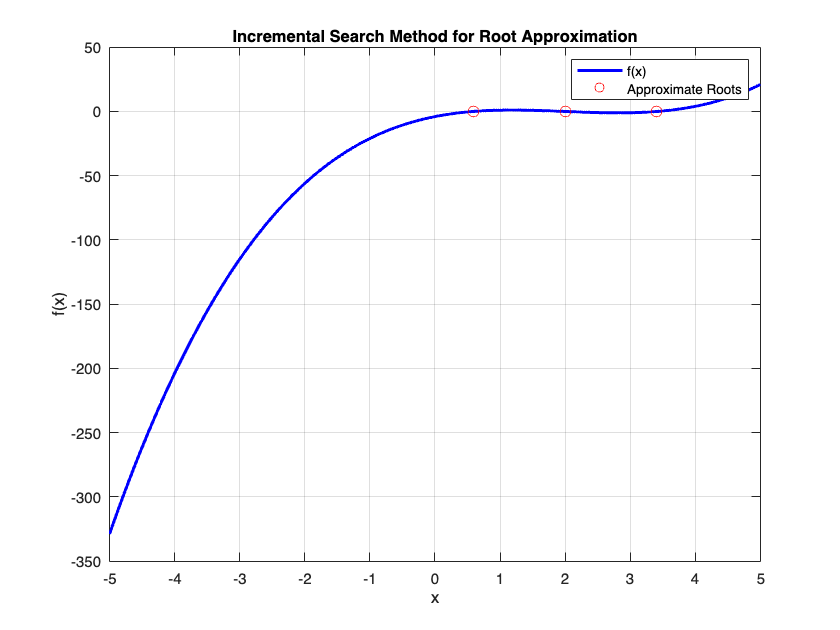

% Create a plot of the function
figure;
x_values = -5:0.01:5; % Higher resolution for smoother curve
y_values = f(x_values);
plot(x_values, y_values, 'b', 'LineWidth', 2);
hold on;

% Mark the approximate roots on the plot
scatter(rounded_roots, rounded_values_at_roots, 50, 'r');
grid on;

% Labels and title
xlim([-5, 5]);
xlabel('x');
ylabel('f(x)');
title('Incremental Search Method for Root Approximation');
legend('f(x)', 'Approximate Roots');

## **P4-9**

**[Preparing Open Method for Use With Closed Method]** Rewrite your script from Q8 to output 3 intervals where the roots are located between.

% Define the equation
f = @(x) x.^3 - 6*x.^2 + 10*x - 4;

% Define step size
step_size = 0.1;

% Define the range for searching
x_range = -10:step_size:10;

% Initialize variables to store intervals
intervals = [];

% Loop through the range to find intervals containing roots
for i = 1:length(x_range)-1
    x1 = x_range(i);
    x2 = x_range(i+1);
    
    % Check if the signs of the function values change
    if f(x1) * f(x2) <= 0
        % Store the interval
        intervals = [intervals; x1, x2];
    end
end

% Display the intervals containing roots
disp('The intervals are:');

The intervals are:


disp(intervals);

    0.5000    0.6000
    1.9000    2.0000
    2.0000    2.1000
    3.4000    3.5000



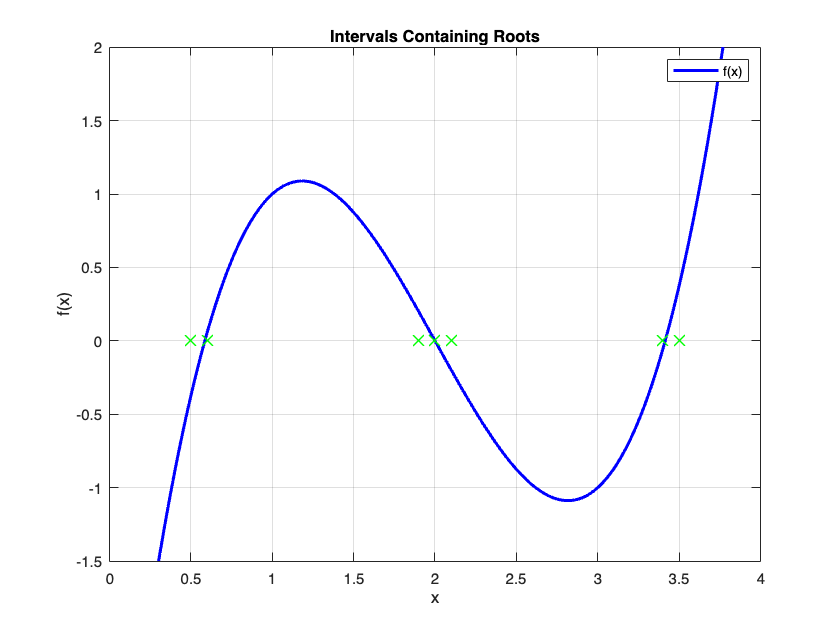


% Create a plot of the function
figure;
x_values = -10:0.01:10; % Higher resolution for smoother curve
y_values = f(x_values);
plot(x_values, y_values, 'b', 'LineWidth', 2);
hold on;

% Mark the intervals containing roots on the plot
for i = 1:size(intervals, 1)
    x_interval = intervals(i,:);
    plot(x_interval, 0, 'gx', 'MarkerSize', 10, 'LineWidth', 1);
end

grid on;

% Labels and title
xlim([0, 4]);
ylim([-1.5, 2]);
xlabel('x');
ylabel('f(x)');
title('Intervals Containing Roots');
legend('f(x)');

## **P4-10**

**[Generalising Method to Any Function]** Write a Matlab function file that implements the Incremental Search Method. The user should be able to input a function f(x), step size h, and range of values to search between [x0,xend]. The output should be a list of brackets (intervals) containing each root. 

Test your function with the function          

## 
$$f\left(x\right)=\sin \left(10x\right)+\cos \left(3x\right)$$


on the interval [3, 6] with step sizes of 0.06 and 0.03.

% Define the function
f = @(x) sin(10*x) + cos(3*x);

% Define the interval and step sizes
x0 = 3;
xend = 6;
step_size1 = 0.06;
step_size2 = 0.03;

% Find brackets using the Incremental Search Method
brackets1 = incrementalSearch(f, x0, xend, step_size1);
brackets2 = incrementalSearch(f, x0, xend, step_size2);

% Display the brackets
disp('Brackets with step size 0.06:');

Brackets with step size 0.06:


disp(brackets1);

    3.2400    3.3000
    3.3600    3.4200
    3.7200    3.7800
    4.2000    4.2600
    4.2600    4.3200
    4.6800    4.7400
    5.6400    5.7000



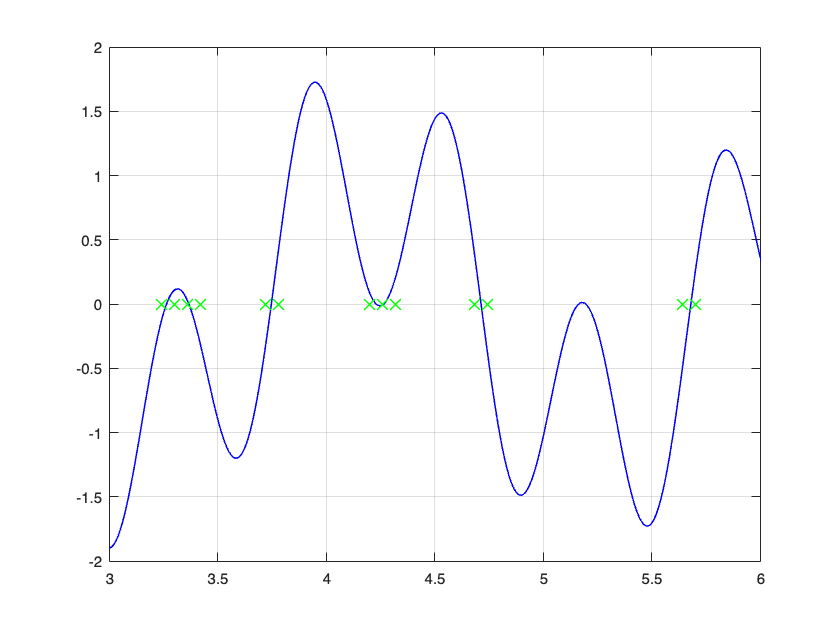

figure;
x_values = 0:0.01:10;
y_values = f(x_values);
plot(x_values, y_values, 'b', 'LineWidth', 1);
hold on;

for i = 1:size(brackets1, 1)
    x_interval = brackets1(i,:);
    plot(x_interval, 0, 'gx', 'MarkerSize', 10, 'LineWidth', 1);
end

grid on;

xlim([3, 6]);
ylim([-2, 2]);

disp('Brackets with step size 0.03:');

Brackets with step size 0.03:


disp(brackets2);

    3.2400    3.2700
    3.3600    3.3900
    3.7200    3.7500
    4.2000    4.2300
    4.2600    4.2900
    4.7100    4.7400
    5.1600    5.1900
    5.1900    5.2200
    5.6700    5.7000



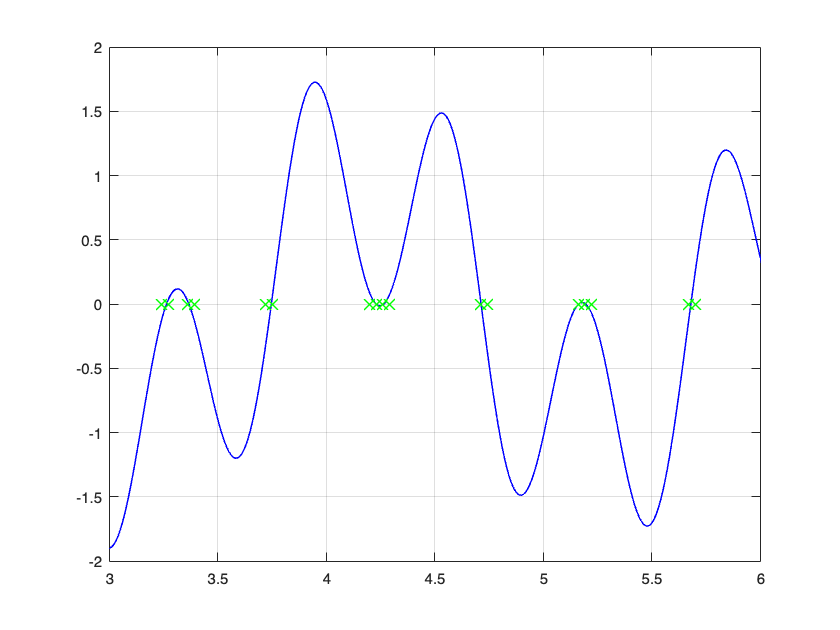

figure;
x_values = 0:0.01:10;
y_values = f(x_values);
plot(x_values, y_values, 'b', 'LineWidth', 1);
hold on;

for i = 1:size(brackets2, 1)
    x_interval = brackets2(i,:);
    plot(x_interval, 0, 'gx', 'MarkerSize', 10, 'LineWidth', 1);
end

grid on;

xlim([3, 6]);
ylim([-2, 2]);

function brackets = incrementalSearch(f, x0, xend, h)
    brackets = [];
    x = x0;
    while x <= xend - h
        x1 = x;
        x2 = x + h;
        if f(x1) * f(x2) < 0
            brackets = [brackets; [x1, x2]];
        end
        x = x2;
    end
end